# Read A ROS Image Message In Simulink

Start a ROS network.

rosinit

Launching ROS Core...
....Done in 4.236 seconds.
Initializing ROS master on http://172.21.16.85:53224.
Initializing global node /matlab_global_node_92597 with NodeURI http://ah-avijayar:61421/ and MasterURI http://localhost:53224.


Load sample messages to send including a sample image message, `img`. Create a publisher to send a ROS `Image` message on the `'/image_test'` topic. Specify the message type as `'/sensor_msgs/Image'`. Send the image message.

imgcell = load('imgdata.mat','img');
img = imgcell.img;
pub = rospublisher('/image_test','sensor_msgs/Image');
send(pub,img)

Open the Simulink® model for subscribing to the ROS message and reading in the image from the ROS.

Ensure that the `Subscribe` block is subscribing to the `'/image_test'` topic. Under** Simulation** tab, select **ROS Toolbox **> **Variable Size Messages**. Notice that the **Use default limits for this message type** is clear. Then, in the **Maximum length** column, verify that the `data` property of the `sensor_msgs/Image` message has a value greater than the number of pixels in the image (921600). Run the model.

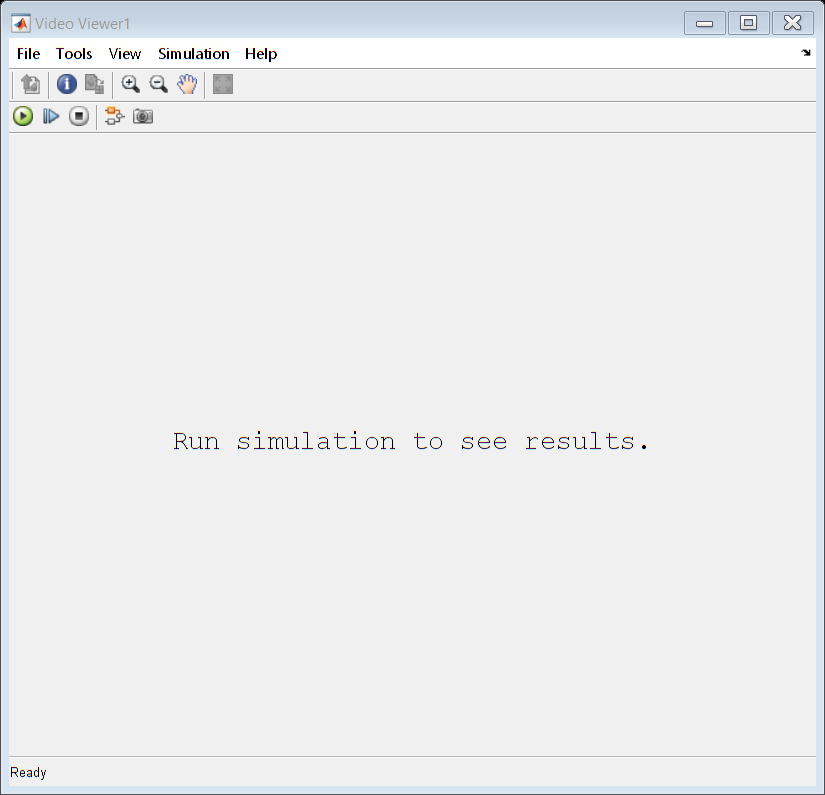

open_system('read_image_example_model.slx')

Run the model. The `Video Viewer` shows the sample image.

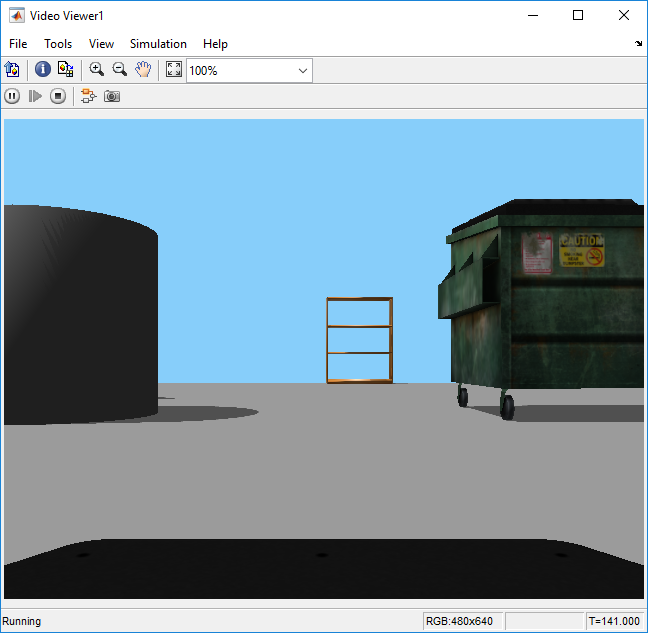

Stop the simulation and shut down the ROS network.

rosshutdown

Shutting down global node /matlab_global_node_92597 with NodeURI http://ah-avijayar:61421/ and MasterURI http://localhost:53224.
Shutting down ROS master on http://172.21.16.85:53224.


*Copyright 2012 The MathWorks, Inc.*